## Planar Moment of Inertia of a Right Triangle

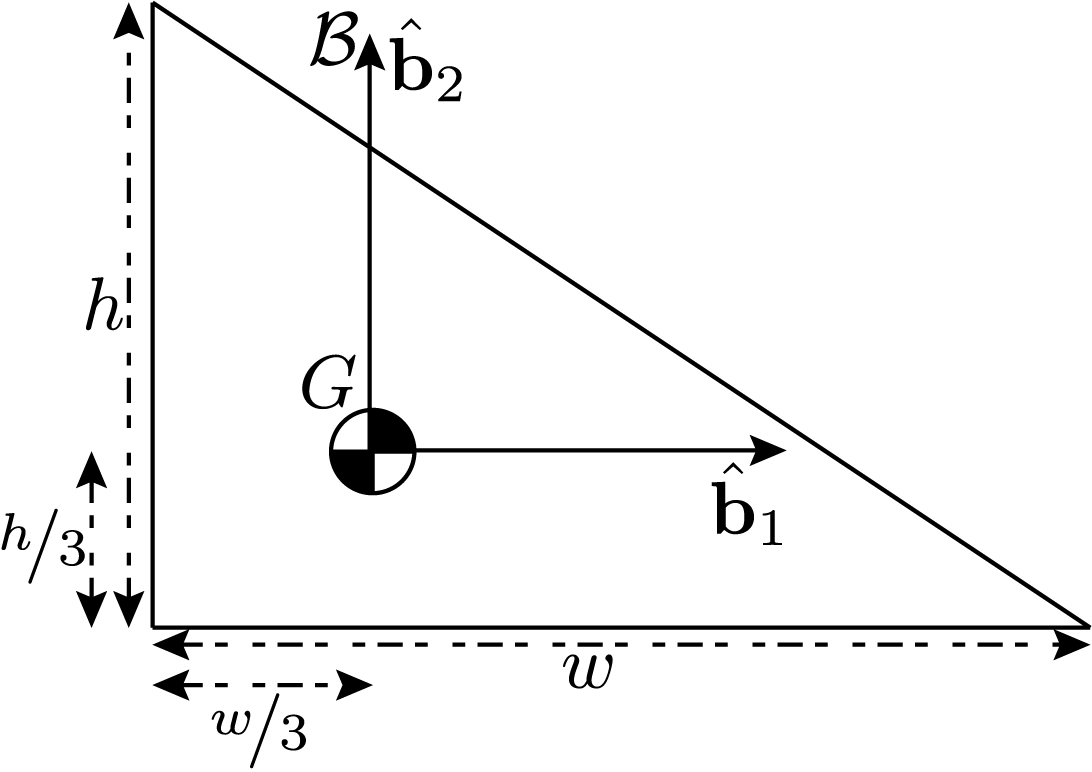

First, let's verify the location of the center of mass. We will set our coordinate origin $O$ in the bottom, right-hand corner of the triangle (at the right angle) and describe the position of each mass element as: $\mathbf r_{\mathrm{d}{m}/O} = x \mathbf{\hat{b}}_1 + y \mathbf{\hat{b}}_2$

syms m h w 'positive' % these are striclty positive quantities
syms x y 'real' % these are real, but not necessarily positive

r_dmO = [x;y;0]

$$r\_dmO = \left(\begin{array}{c} x\\ y\\ 0 \end{array}\right)$$

We must not integrate over the limits of the body.  $x$ goes from 0 to $w$ whereas $y$ goes from 0 to $h - \frac{h}{w}x$. Since the $y$ limit has an $x$ dependence, we must integrate over it first.

tmp = int(int(r_dmO,y, 0,h - h/w*x), x, 0 ,w)

$$tmp = \left(\begin{array}{c} \frac{h\,w^{2}}{6}\\ \frac{h^{2}\,w}{6}\\ 0 \end{array}\right)$$

Finally, we need to scale this by the areal density over the mass, which in this case equals $\frac{2}{hw}$

r_GO = 2/h/w*tmp

$$r\_GO = \left(\begin{array}{c} \frac{w}{3}\\ \frac{h}{3}\\ 0 \end{array}\right)$$

At this point, we could redefine our coordinates to be with respect to the center of mass, but it is actually easier to keep the original $x$ and $y$ definitions, as we then do not need to change our limits of integration for computing the MOI

r_dmG = r_dmO-r_GO

$$r\_dmG = \left(\begin{array}{c} x-\frac{w}{3}\\ y-\frac{h}{3}\\ 0 \end{array}\right)$$

We now need to integrate over $\Vert \mathbf{r}_{\mathrm{d}m/G} \Vert^2$

r_dmG2 = dot(r_dmG, r_dmG)

$$r\_dmG2 = {\left(\frac{h}{3}-y\right)}^{2}+{\left(\frac{w}{3}-x\right)}^{2}$$

tmp2 = int(int(r_dmG2,y, 0,h - h/w*x), x, 0 ,w)

$$tmp2 = \frac{h\,w\,\left(h^{2}+w^{2}\right)}{36}$$

Finally, we scale this by the areal density

I_G = m/(h*w/2)*tmp2

$$I\_G = \frac{m\,\left(h^{2}+w^{2}\right)}{18}$$